# Train the Flood Classification Network

Instructions are in the task pane to the left. This activity is ungraded.

Import data set and corresponding labels. Preprocess the data and import it into a cell array.

pathToSignals = "../data/flooddata";
rng default
sigds = signalDatastore(pathToSignals, ...
    "IncludeSubfolders", true, ...
    "SignalVariableNames", ["ax" "ay" "az"], ...
    "ReadOutputOrientation", "row");
labels = folders2labels(pathToSignals);
labels = renamecats(labels, ["0.0 ft" "0.19 ft" "2.5 ft" "4.5 ft"]);
sigt = transform(sigds, @prepsig);
sigdata = readall(sigt);

Split the data set into three sets for training, validation, and testing.

idx = splitlabels(labels, [0.8 0.1]);
traindata = sigdata(idx{1});
trainlabels = labels(idx{1});
valdata = sigdata(idx{2});
vallabels = labels(idx{2});
testdata = sigdata(idx{3});
testlabels = labels(idx{3});

Create layers using the Deep Network Designer.

layers = [  sequenceInputLayer(3, "Name", "input")
            lstmLayer(128, "Name", "lstm", "OutputMode", "last")
            dropoutLayer(0.5, "Name", "dropout")
            fullyConnectedLayer(4, "Name", "fc")
            softmaxLayer("Name", "softmax")
            classificationLayer("Name", "classification")];

Create basic training options.

opts = trainingOptions("adam", ...
    "ValidationData", {valdata vallabels}, ...
    "Plots", "training-progress");

**Train the network!**

This will take up to thirty seconds to execute.

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |       28.91% |       45.83% |       1.3877 |       1.3732 |          0.0010 |
|      30 |          30 |       00:00:13 |       60.16% |       54.17% |       0.8881 |       1.0827 |          0.0010 |
|======================================================================================================================|
Training finished: Max epochs completed.


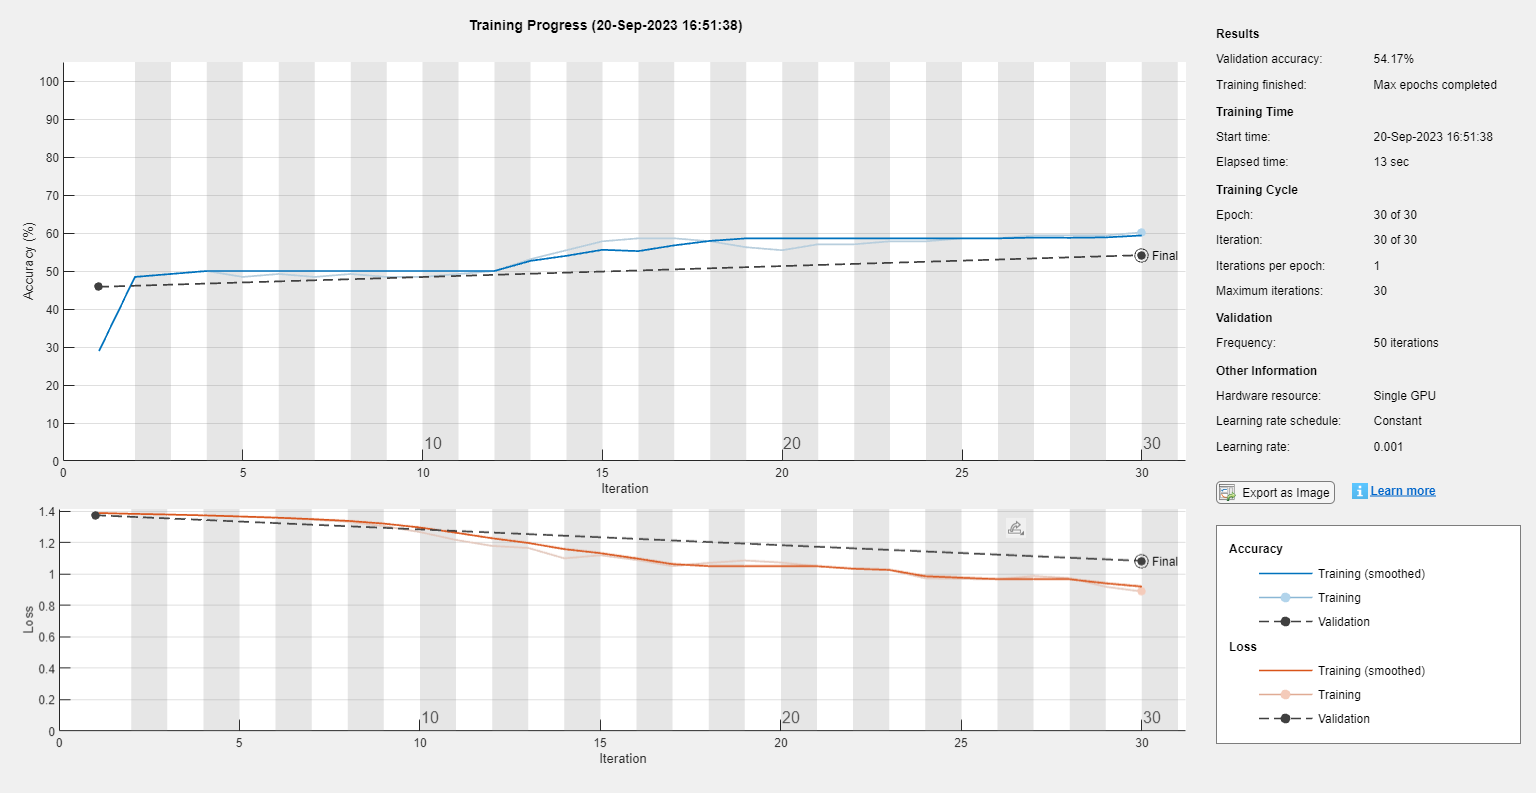

floodnet =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'classification'}


floodnet = trainNetwork(traindata, trainlabels, layers, opts)

Transformation function for the data set.

function sig = prepsig(sigin)
    sig = cell2mat(sigin);
    sig = sig';
    sig = {sig};
end